# CAP 4630 - Intro to AI - FAU - Dr. Marques - Summer 2019

## 1.1: Loading a pre-trained "AlexNet"

% Ensure that you have downloaded and installed the 
% "Deep Learning Toolbox Model for AlexNet Network" support package. 

% See https://www.mathworks.com/matlabcentral/fileexchange/59133-deep-learning-toolbox-model-for-alexnet-network
% and
% https://www.mathworks.com/help/deeplearning/ug/pretrained-convolutional-neural-networks.html
% for additional information.

model = alexnet;

## 1.3: Inspect the CNN's layers

model.Layers

ans =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Grouped Convolution           2 groups of 128 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0


% The intermediate layers make up the bulk of the CNN. These are a series
% of convolutional layers, interspersed with rectified linear units (ReLU)
% and max-pooling layers [2]. Following the these layers are 3
% fully-connected layers.

% The final layer is the classification layer and its properties depend on
% the classification task. In this example, the CNN model that was loaded
% was trained to solve a 1000-way classification problem. Thus the
% classification layer has 1000 classes from the ImageNet dataset. 

% Inspect the last layer
model.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'output'
         Classes: [1000×1 categorical]
      OutputSize: 1000

   Hyperparameters
    LossFunction: 'crossentropyex'



% Number of class names for ImageNet classification task
numel(model.Layers(end).ClassNames)

ans = 1000


% Analyze the AlexNet in more detail using the network analyzer 
% to display an interactive visualization of the network architecture 
% and detailed information about the network layers.
analyzeNetwork(model)

% Note that the CNN model is not going to be used for the original
% classification task. It is going to be re-purposed to solve a different
% classification task on the pets dataset.

## 1.4: Inspect the network weights for the second convolutional layer

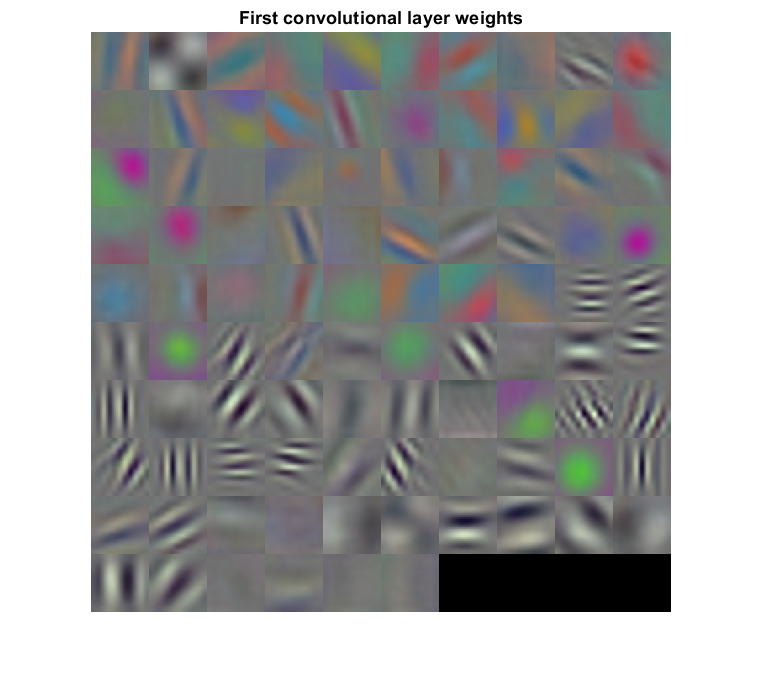

% Each layer of a CNN produces a response, or activation, to an input
% image. However, there are only a few layers within a CNN that are
% suitable for image feature extraction. The layers at the beginning of the
% network capture basic image features, such as edges and blobs. To see
% this, visualize the network filter weights from the first convolutional
% layer. This can help build up an intuition as to why the features
% extracted from CNNs work so well for image recognition tasks. Note that
% visualizing deeper layer weights is beyond the scope of this example. You
% can read more about that in the work of Zeiler and Fergus [4].

% Get the network weights for the second convolutional layer
w1 = model.Layers(2).Weights;

% Scale and resize the weights for visualization
w1 = mat2gray(w1);
w1 = imresize(w1,5); 

% Display a montage of network weights. 
figure
montage(w1)
title('First convolutional layer weights')

## Part 2: Set up image data

## 2.1: Load simplified dataset and build image store

dataFolder = './data/PetImages';
categories = {'cat', 'dog'};
imds = imageDatastore(fullfile(dataFolder, categories), 'LabelSource', 'foldernames');
tbl = countEachLabel(imds);
disp (tbl)

    Label    Count
    _____    _____

     cat      20  
     dog      20  




% Use the smallest overlap set
% (useful when the two classes have different number of elements but not
% needed in this case)
minSetCount = min(tbl{:,2});

% Use splitEachLabel method to trim the set.
imds = splitEachLabel(imds, minSetCount, 'randomize');

% Notice that each set now has exactly the same number of images.
countEachLabel(imds)

ans = 2×2 table
    Label    Count
    _____    _____

     cat      20  
     dog      20  


## 2.2: Pre-process Images For CNN

AlexNet can only process RGB images that are 227-by-227. To avoid re-saving all the images to this format, setup the `imds` read function, `imds.ReadFcn`, to pre-process images on-the-fly. The `imds.ReadFcn` is called every time an image is read from the `ImageDatastore`.

Set the ImageDatastore ReadFcn

imds.ReadFcn = @(filename)readAndPreprocessImage(filename);

## 2.3: Divide data into training and validation sets

[trainingSet, validationSet] = splitEachLabel(imds, 0.7, 'randomized');

countEachLabel(trainingSet)

ans = 2×2 table
    Label    Count
    _____    _____

     cat      14  
     dog      14  


countEachLabel(validationSet)

ans = 2×2 table
    Label    Count
    _____    _____

     cat       6  
     dog       6  


## 3.1: Freeze all but last three layers

layersTransfer = model.Layers(1:end-3);
numClasses = 2; % cat and dog

layers = [
    layersTransfer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];

## 3.2: Configure training options

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',validationSet, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');

## 3.3: Retrain network

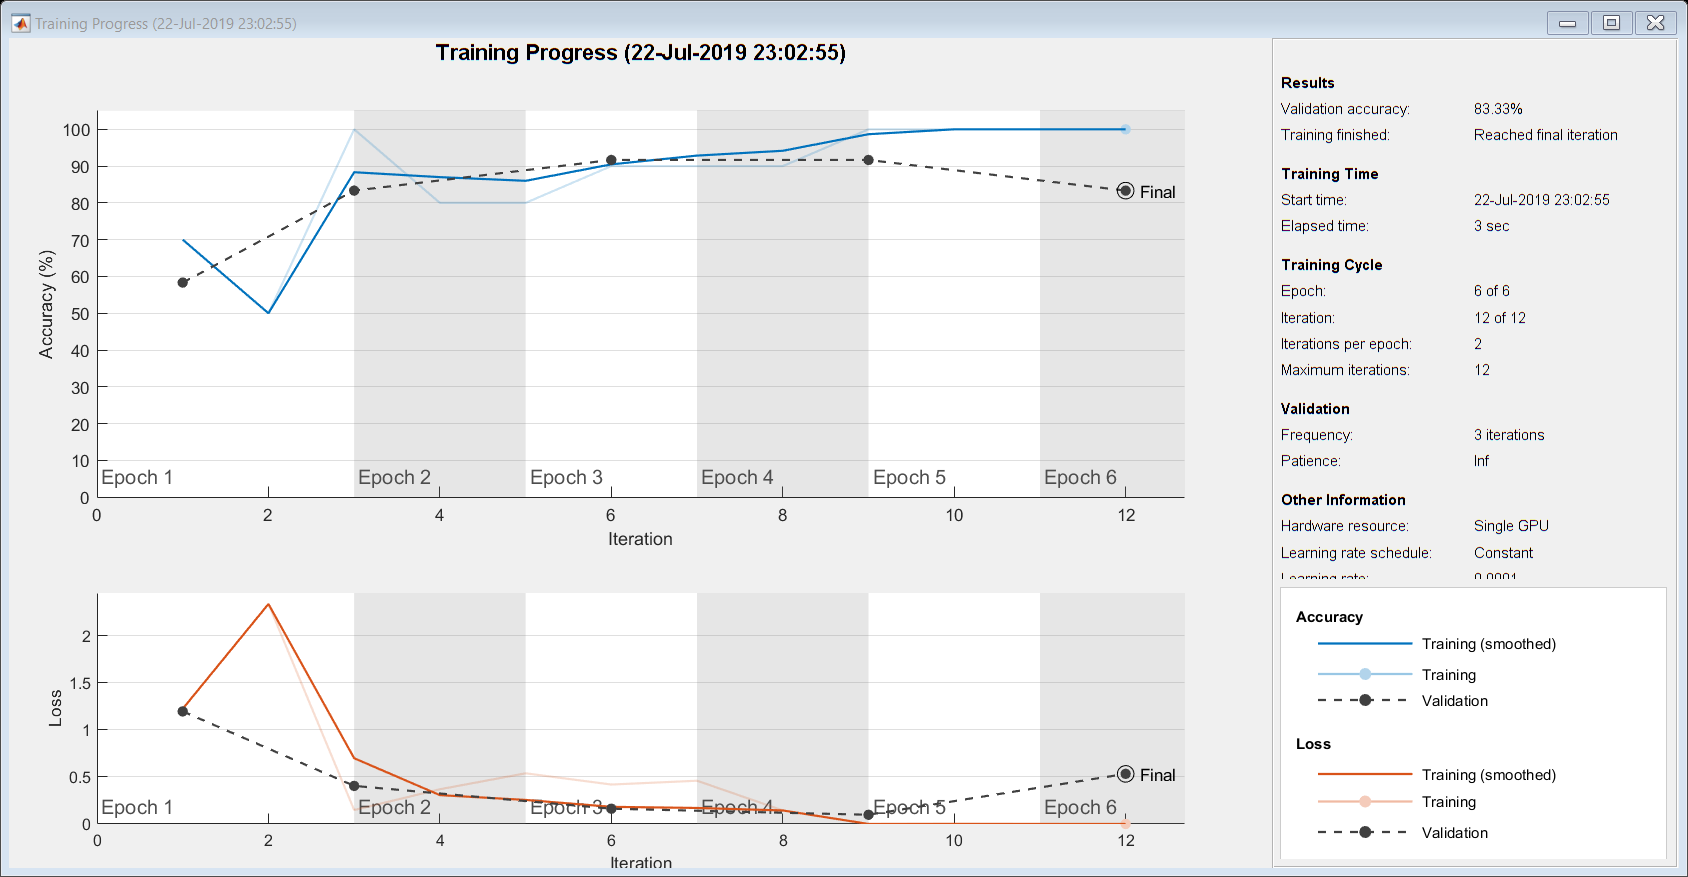

modelTransfer = trainNetwork(trainingSet,layers,options);

## 3.4: Classify the validation images using the fine-tuned network.

[YPred,scores] = classify(modelTransfer,validationSet);

## 3.5: Calculate the classification accuracy on the validation set.

Accuracy is the fraction of labels that the network predicts correctly.

YValidation = validationSet.Labels;
accuracy = mean(YPred == YValidation);
fprintf("The validation accuracy is: %.2f %%\n", accuracy * 100);

The validation accuracy is: 83.33 %


## 3.6: Test it on unseen images

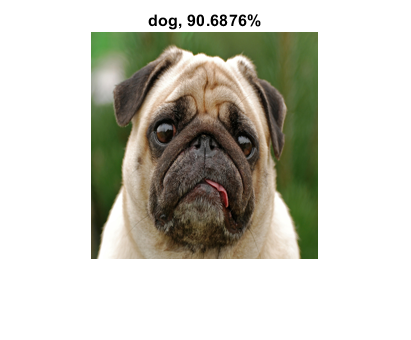

newImage1 = './dog.jpg'; % any dog image should do!
img1 = readAndPreprocessImage(newImage1);
YPred1 = predict(modelTransfer,img1);
[confidence1,idx1] = max(YPred1);
label1 = categories{idx1};
% Display test image and assigned label
figure
imshow(img1)
title(string(label1) + ", " + num2str(100*confidence1) + "%");

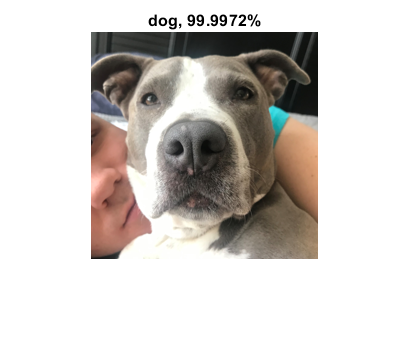


newImage7 = './dog2.jpg'; % own test picture
img7 = readAndPreprocessImage(newImage7);
YPred7 = predict(modelTransfer,img7);
[confidence7,idx7] = max(YPred7);
label7 = categories{idx7};
% Display test image and assigned label
figure
imshow(img7)
title(string(label7) + ", " + num2str(100*confidence7) + "%");

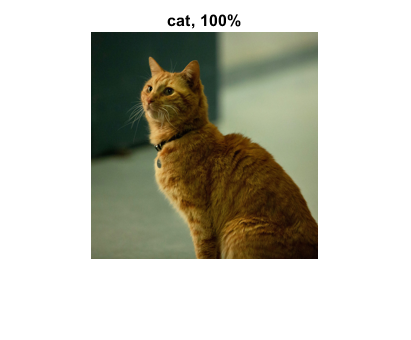


newImage2 = './cat.jpg'; % any cat image should do!
img2 = readAndPreprocessImage(newImage2);
YPred2 = predict(modelTransfer,img2);
[confidence2,idx2] = max(YPred2);
label2 = categories{idx2};
% Display test image and assigned label
figure
imshow(img2)
title(string(label2) + ", " + num2str(100*confidence2) + "%");

## 3.7: Test it on unseen images: Your turn!

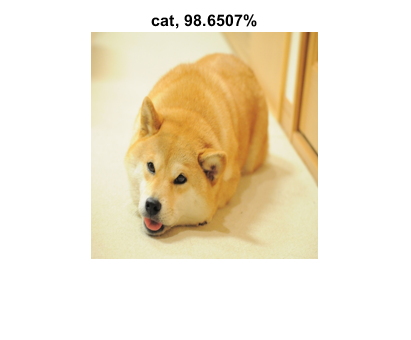

% What about the iconic "Doge"?
% ENTER YOUR CODE HERE
newImage3 = './doge.jpg';
img3 = readAndPreprocessImage(newImage3);
YPred3 = predict(modelTransfer,img3);
[confidence3,idx3] = max(YPred3);
label3 = categories{idx3};
% Display test image and assigned label
figure
imshow(img3)
title(string(label3) + ", " + num2str(100*confidence3) + "%");

## 4.1: Defining the imageAugmenter object

In our case, we shall use an augmented image datastore to randomly flip the training images along the vertical axis and randomly translate them up to 30 pixels and scale them up to 10% horizontally and vertically.

pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);

## 4.2: Building the augmented training and validation sets

inputSize = model.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),trainingSet, ...
    'DataAugmentation',imageAugmenter);

disp(augimdsTrain.NumObservations) % You should see 28

    28




augimdsValidation = augmentedImageDatastore(inputSize(1:2),validationSet);

disp(augimdsValidation.NumObservations) % You should see 12

    12



## 4.3: Train the network with augmented datasets

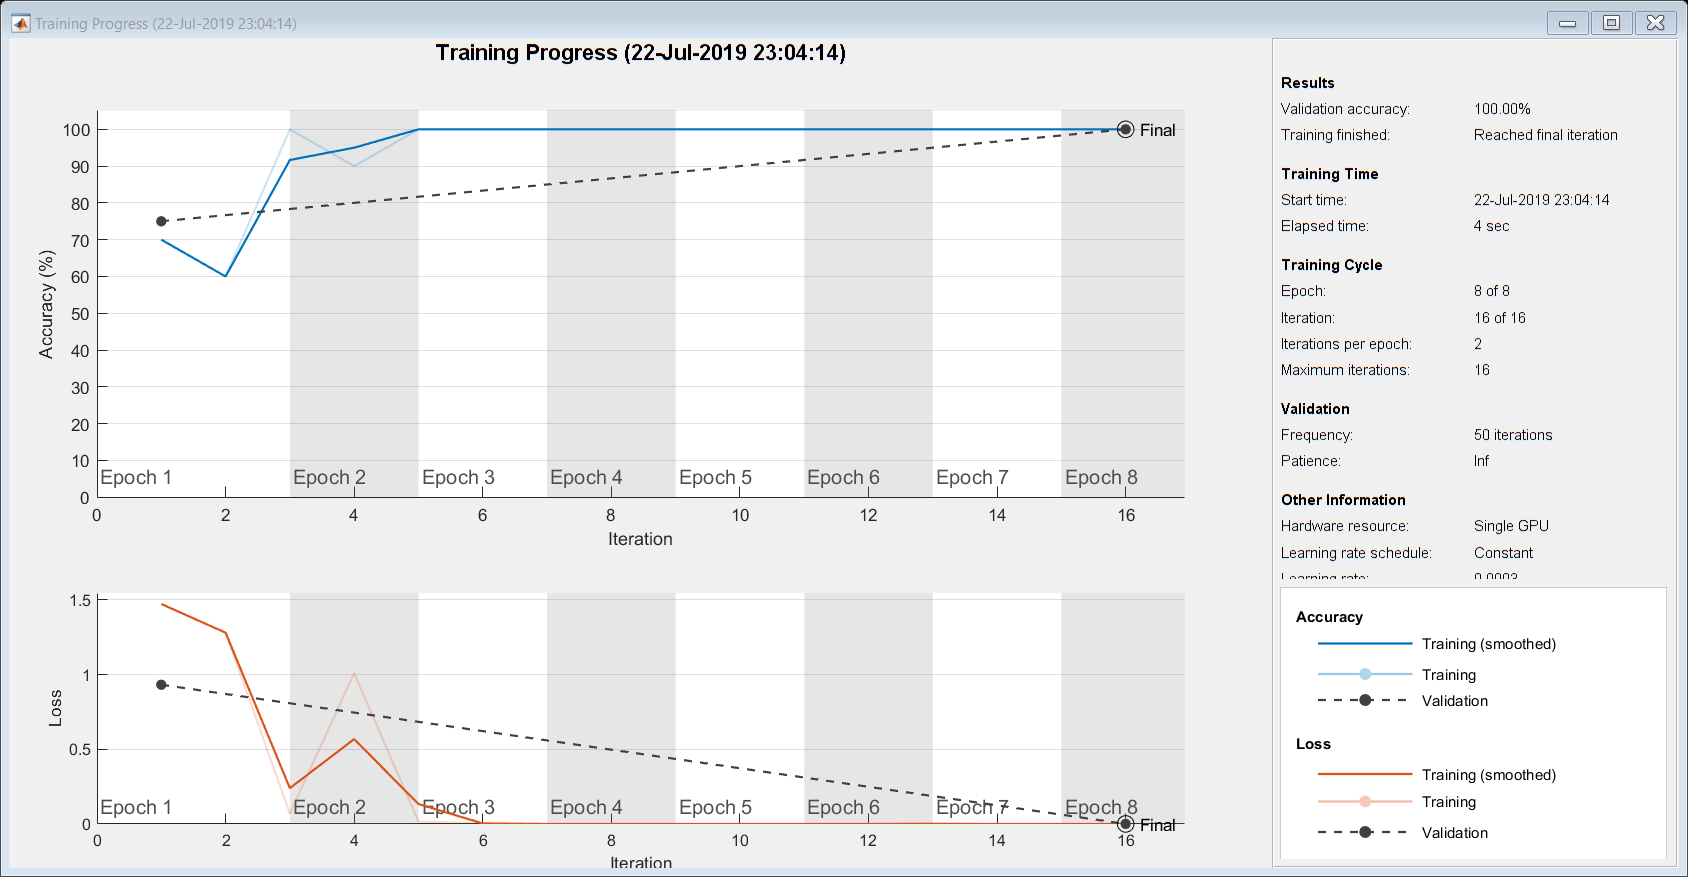

miniBatchSize = 10;
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',8, ...
    'InitialLearnRate',3e-4, ...
    'ValidationData',augimdsValidation, ...
    'Verbose',false, ...
    'Plots','training-progress');

modelAug = trainNetwork(augimdsTrain,layers,options);

## 4.4: Classify the validation images using the fine-tuned network.

[YPredAug,probsAug] = classify(modelAug,augimdsValidation);

## 4.5: Calculate the classification accuracy on the validation set.

Accuracy is the fraction of labels that the network predicts correctly.

YValidationAug = validationSet.Labels;
accuracyAug = mean(YPredAug == YValidationAug);
fprintf("The validation accuracy is: %.2f %%\n", accuracyAug * 100);

The validation accuracy is: 100.00 %


## Part 5: Larger datasets

% One possible reason why the accuracy of the classifier was so low 
% might have to do with not enough training data.
% Of course, there are plenty of dogs and cats around (in the Kaggle
% dataset and elsewhere) to circumvent this problem.


% PART 2 RE-RUN
dataFolder2 = './data2/PetImages';
categories = {'cat', 'dog'};
imds2 = imageDatastore(fullfile(dataFolder2, categories), 'LabelSource', 'foldernames');
tbl2 = countEachLabel(imds2);
disp (tbl2)

    Label    Count
    _____    _____

     cat     12500
     dog     12500




minSetCount2 = min(tbl2{:,2});

% Use splitEachLabel method to trim the set.
imds2 = splitEachLabel(imds2, minSetCount2, 'randomize');

% Notice that each set now has exactly the same number of images.
countEachLabel(imds2)

ans = 2×2 table
    Label    Count
    _____    _____

     cat     12500
     dog     12500




% Set the ImageDatastore ReadFcn
imds2.ReadFcn = @(filename)readAndPreprocessImage(filename);

[trainingSet2, validationSet2] = splitEachLabel(imds2, 0.8, 'randomize');

countEachLabel(trainingSet2)

ans = 2×2 table
    Label    Count
    _____    _____

     cat     10000
     dog     10000


countEachLabel(validationSet2)

ans = 2×2 table
    Label    Count
    _____    _____

     cat     2500 
     dog     2500 


## PART 3 RE-RUN

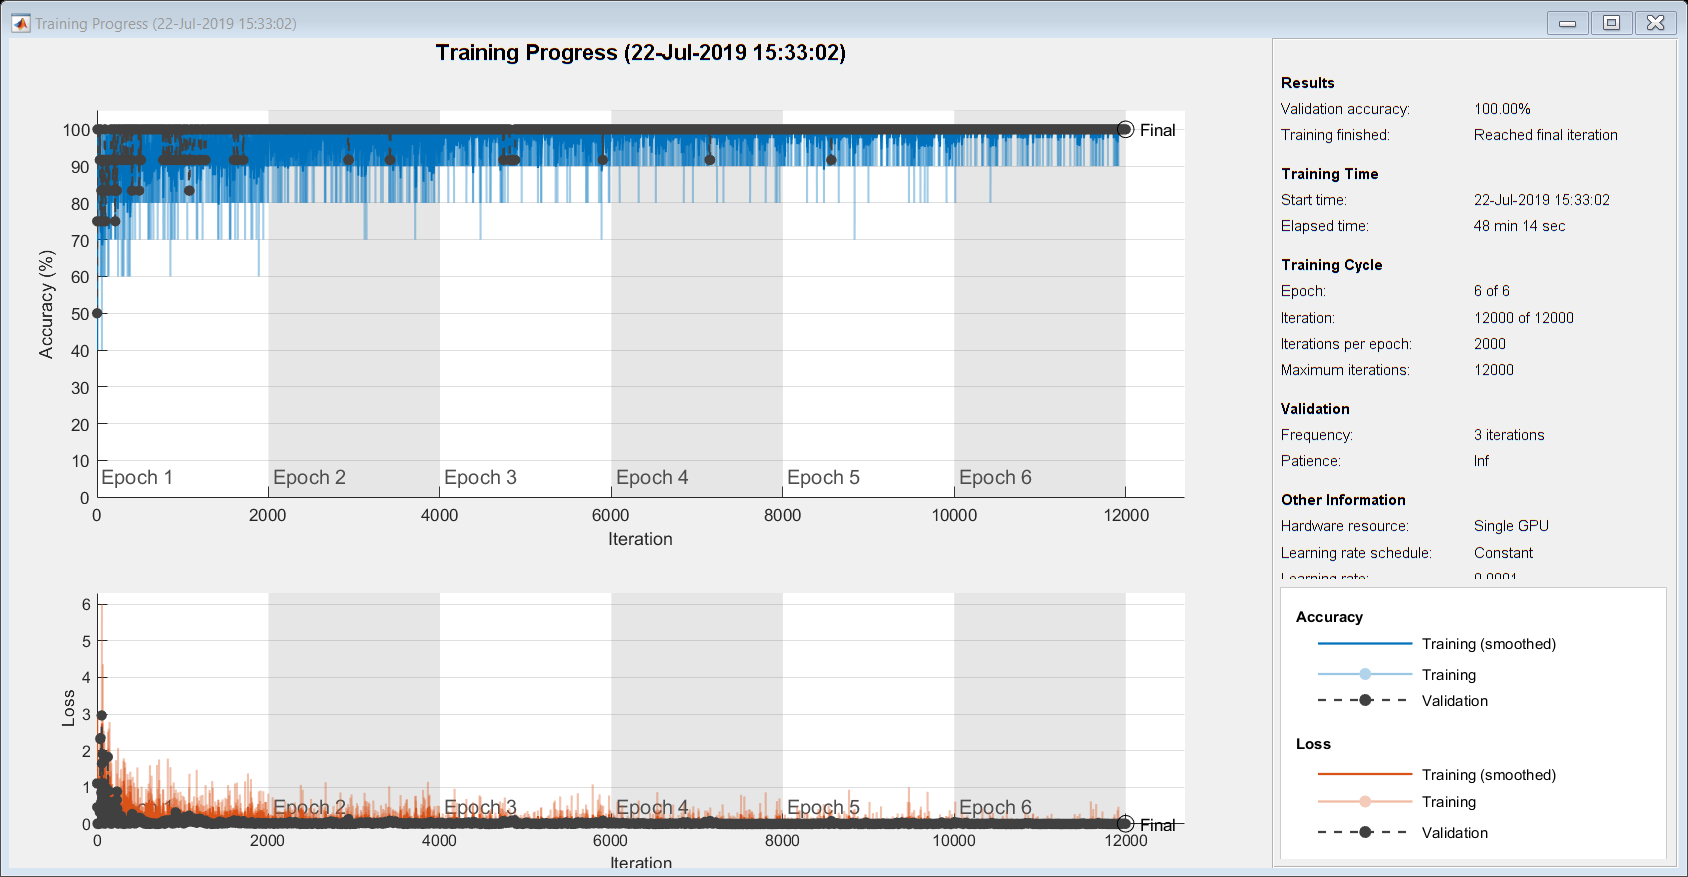

layersTransfer2 = model.Layers(1:end-3);
numClasses = 2; % cat and dog

layers2 = [
    layersTransfer2
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];


options = trainingOptions('sgdm', ...
    'ExecutionEnvironment','gpu',...
    'MiniBatchSize', 10, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',validationSet, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');


modelTransfer2 = trainNetwork(trainingSet2,layers2,options);



[YPredx,scores2] = classify(modelTransfer2,validationSet2);


% Accuracy is the fraction of labels that the network predicts correctly.

YValidation2 = validationSet2.Labels;
accuracy2 = mean(YPredx == YValidation2);
fprintf("The validation accuracy is: %.2f %%\n", accuracy2 * 100);

The validation accuracy is: 96.94 %


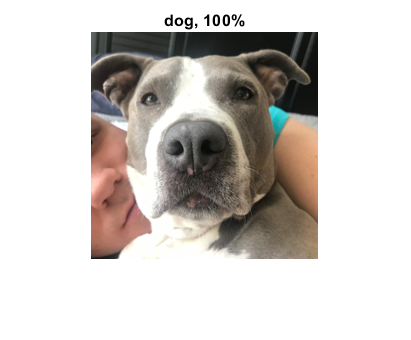


newImage8 = './dog2.jpg'; % own test picture
img8 = readAndPreprocessImage(newImage8);
YPred8 = predict(modelTransfer2,img8);
[confidence8,idx8] = max(YPred8);
label8 = categories{idx8};
% Display test image and assigned label
figure
imshow(img8)
title(string(label8) + ", " + num2str(100*confidence8) + "%");


newImage5 = './cat.jpg'; % any cat image should do!
img5 = readAndPreprocessImage(newImage5);
YPred5 = predict(modelTransfer2,img5);
[confidence5,idx5] = max(YPred5);
label5 = categories{idx5};
% Display test image and assigned label
figure
imshow(img5)
title(string(label5) + ", " + num2str(100*confidence5) + "%");

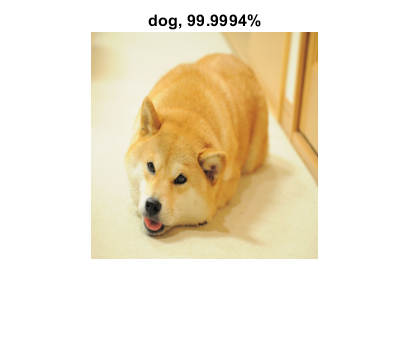


% What about "doge"?
newImage6 = './doge.jpg';
img6 = readAndPreprocessImage(newImage6);
YPred6 = predict(modelTransfer2,img6);
[confidence6,idx6] = max(YPred6);
label6 = categories{idx6};
% Display test image and assigned label
figure
imshow(img6)
title(string(label6) + ", " + num2str(100*confidence6) + "%");

## PART 4 RE-RUN

pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true, ...
    'RandXTranslation',pixelRange, ...
    'RandYTranslation',pixelRange, ...
    'RandXScale',scaleRange, ...
    'RandYScale',scaleRange);

inputSize = model.Layers(1).InputSize;
augimdsTrain2 = augmentedImageDatastore(inputSize(1:2),trainingSet2, ...
    'DataAugmentation',imageAugmenter);

disp(augimdsTrain2.NumObservations) % You should see 20000

       20000




augimdsValidation2 = augmentedImageDatastore(inputSize(1:2),validationSet2);

disp(augimdsValidation2.NumObservations) % You should see 5000

        5000



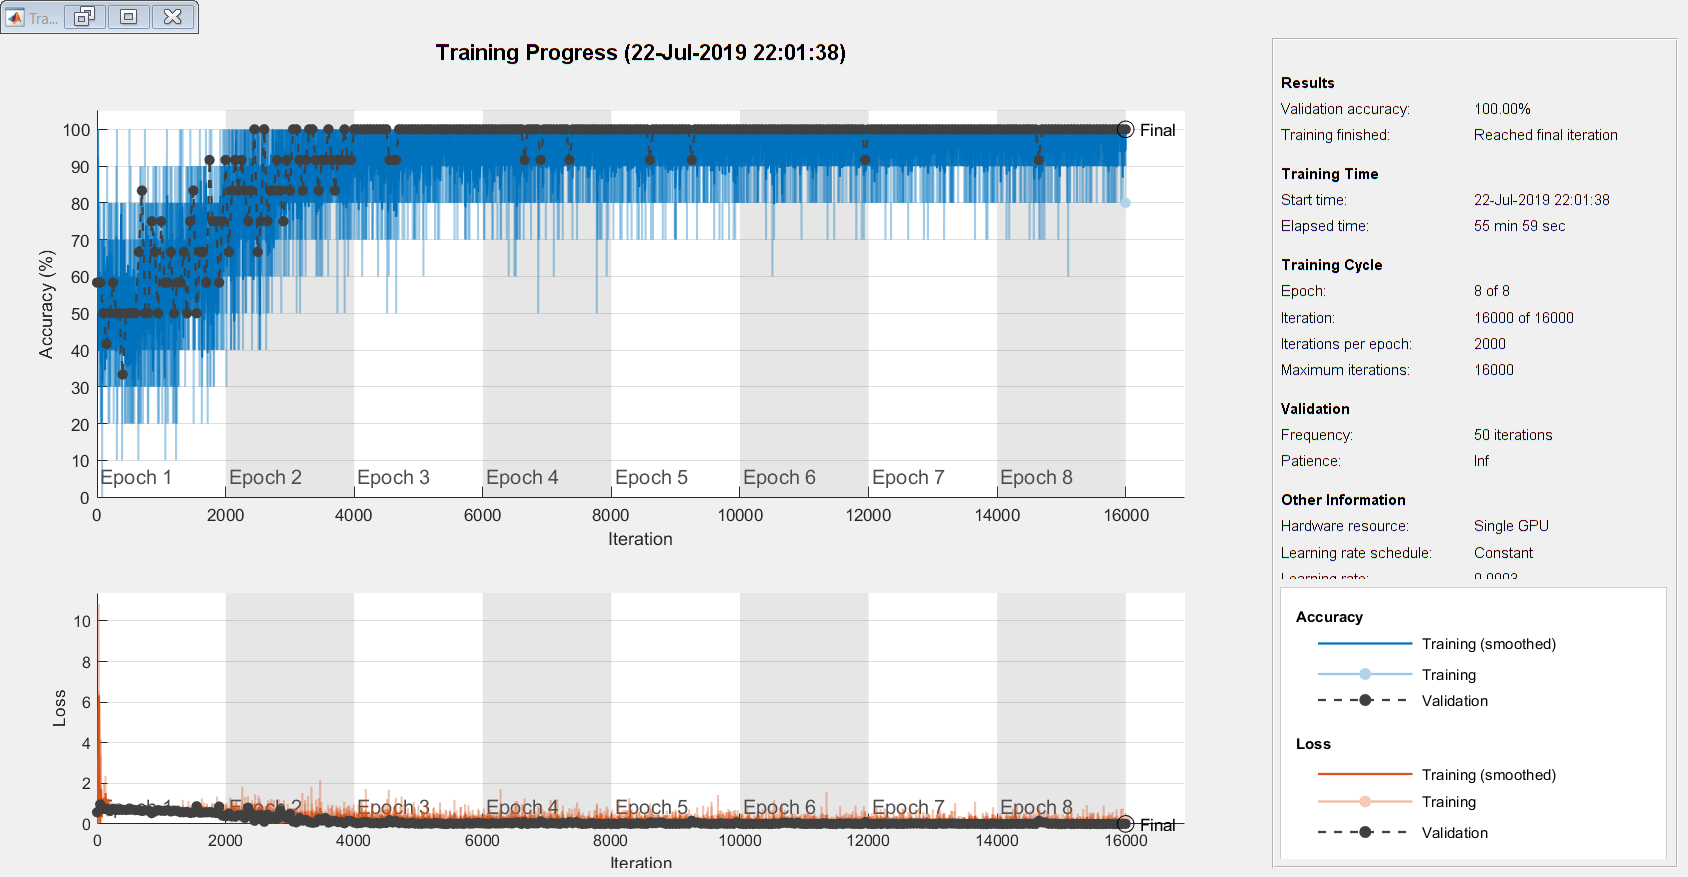


miniBatchSize = 10;
options = trainingOptions('sgdm', ...
    'ExecutionEnvironment','gpu',...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',8, ...
    'InitialLearnRate',3e-4, ...
    'ValidationData',augimdsValidation, ...
    'Verbose',false, ...
    'Plots','training-progress');

modelAug2 = trainNetwork(augimdsTrain2,layers2,options);


[YPredAug2,probsAug] = classify(modelAug2,augimdsValidation2);

YValidationAug2 = validationSet2.Labels;
accuracyAug2 = mean(YPredAug2 == YValidationAug2);
fprintf("The validation accuracy is: %.2f %%\n", accuracyAug2 * 100);

The validation accuracy is: 96.52 %


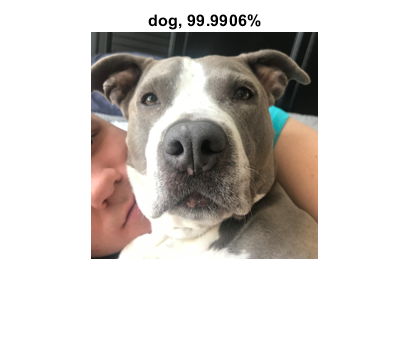


newImage9 = './dog2.jpg'; % own test picture
img9 = readAndPreprocessImage(newImage9);
YPred9 = predict(modelAug2,img9);
[confidence9,idx9] = max(YPred9);
label9 = categories{idx9};
% Display test image and assigned label
figure
imshow(img9)
title(string(label9) + ", " + num2str(100*confidence9) + "%");

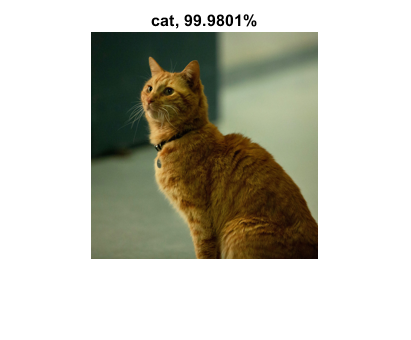


newImage10 = './cat.jpg'; % any cat image should do!
img10 = readAndPreprocessImage(newImage10);
YPred10 = predict(modelAug2,img10);
[confidence10,idx10] = max(YPred10);
label10 = categories{idx10};
% Display test image and assigned label
figure
imshow(img10)
title(string(label10) + ", " + num2str(100*confidence10) + "%");

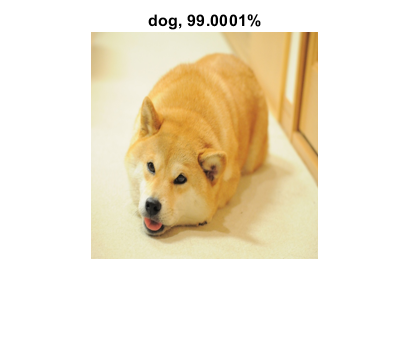


% What about "doge"?
newImage12 = './doge.jpg';
img12 = readAndPreprocessImage(newImage12);
YPred12 = predict(modelAug2,img12);
[confidence12,idx12] = max(YPred12);
label12 = categories{idx12};
% Display test image and assigned label
figure
imshow(img12)
title(string(label12) + ", " + num2str(100*confidence12) + "%");

## Improved Classifier 2

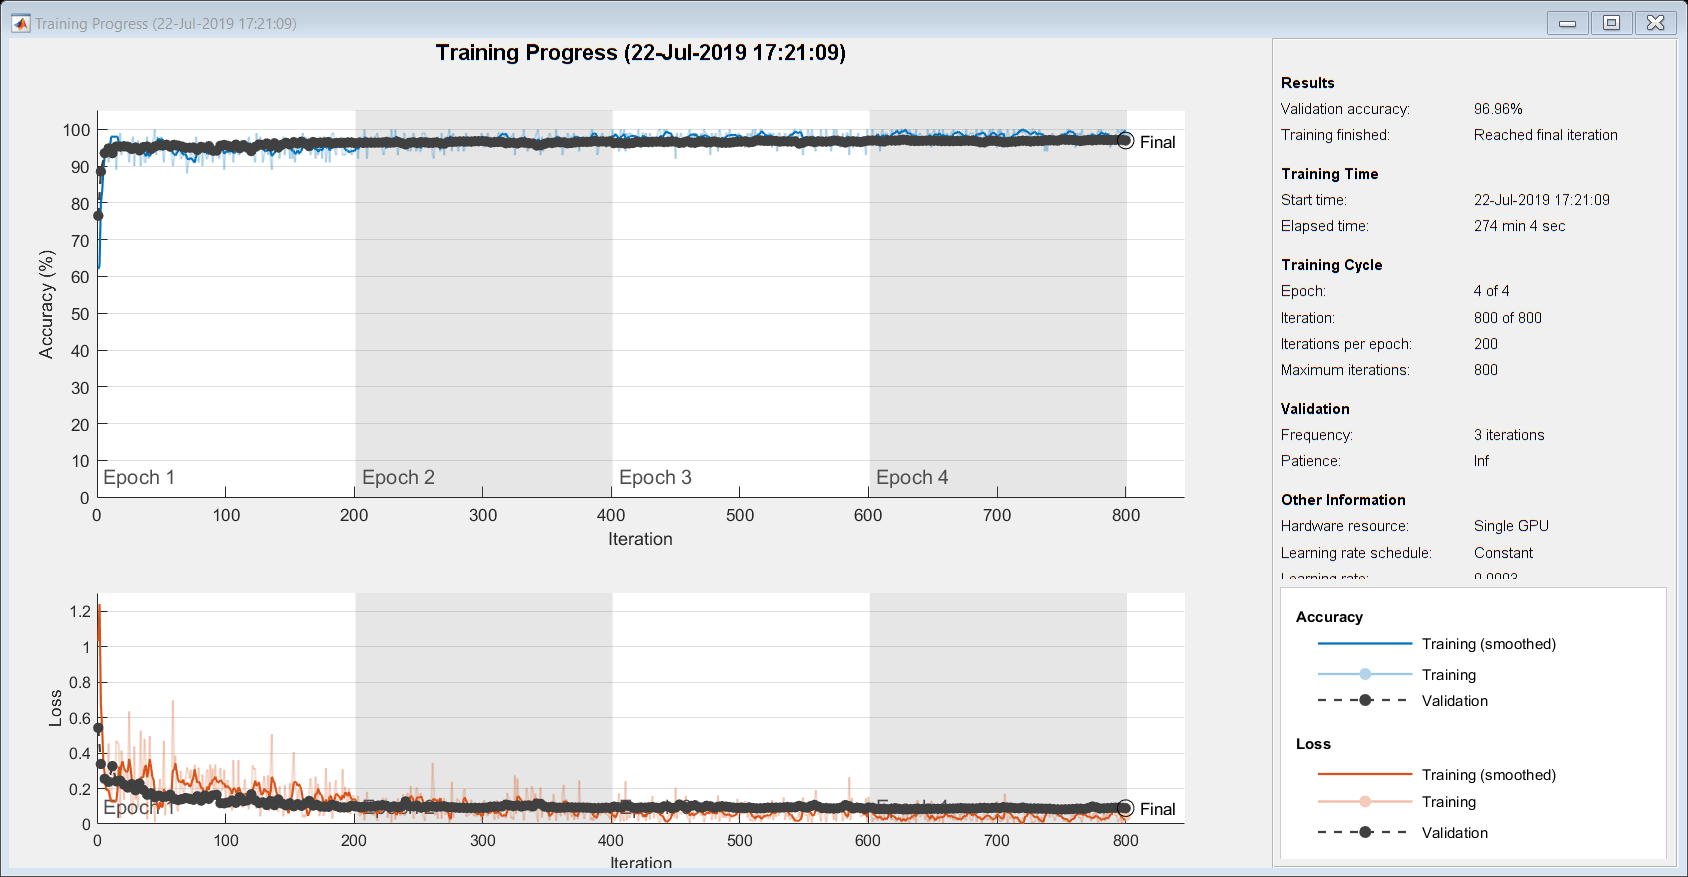

options4 = trainingOptions('sgdm', ...
    'ExecutionEnvironment','gpu',...
    'MiniBatchSize', 100, ...
    'MaxEpochs',4, ...  
    'InitialLearnRate',0.0003, ...
    'Shuffle','every-epoch', ...
    'ValidationData',validationSet2, ...
    'ValidationFrequency',3, ...
    'Verbose',false, ...
    'Plots','training-progress');


modelTransfer3 = trainNetwork(trainingSet2,layers2,options4);



[YPredz,scores3] = classify(modelTransfer3,validationSet2);


% Accuracy is the fraction of labels that the network predicts correctly.

YValidation3 = validationSet2.Labels;
accuracy5 = mean(YPredz == YValidation3);
fprintf("The validation accuracy is: %.2f %%\n", accuracy5 * 100);

The validation accuracy is: 96.96 %



newImage13 = './dog2.jpg'; % own test picture
img13 = readAndPreprocessImage(newImage13);
YPred13 = predict(modelTransfer3,img13);
[confidence13,idx13] = max(YPred13);
label13 = categories{idx13};
% Display test image and assigned label
figure
imshow(img13)
title(string(label13) + ", " + num2str(100*confidence13) + "%");

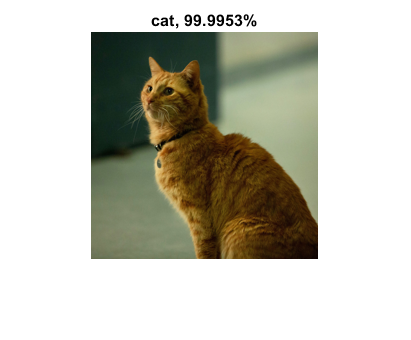


newImage14 = './cat.jpg'; % any cat image should do!
img14 = readAndPreprocessImage(newImage14);
YPred14 = predict(modelTransfer3,img14);
[confidence14,idx14] = max(YPred14);
label14 = categories{idx14};
% Display test image and assigned label
figure
imshow(img14)
title(string(label14) + ", " + num2str(100*confidence14) + "%");

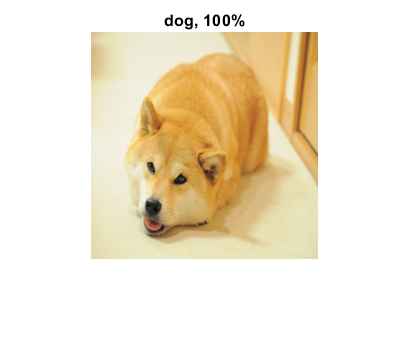


% What about "doge"?
newImage15 = './doge.jpg';
img15 = readAndPreprocessImage(newImage15);
YPred15 = predict(modelTransfer3,img15);
[confidence15,idx15] = max(YPred15);
label15 = categories{idx15};
% Display test image and assigned label
figure
imshow(img15)
title(string(label15) + ", " + num2str(100*confidence15) + "%");

## References

[1] Deng, Jia, et al. "Imagenet: A large-scale hierarchical image database." Computer Vision and Pattern Recognition, 2009. CVPR 2009. IEEE Conference on. IEEE, 2009.

[2] Krizhevsky, Alex, Ilya Sutskever, and Geoffrey E. Hinton. "Imagenet classification with deep convolutional neural networks." Advances in neural information processing systems. 2012.

[3] Vedaldi, Andrea, and Karel Lenc. "MatConvNet-convolutional neural networks for MATLAB." arXiv preprint arXiv:1412.4564 (2014).

[4] Zeiler, Matthew D., and Rob Fergus. "Visualizing and understanding convolutional networks." Computer Vision-ECCV 2014. Springer International Publishing, 2014. 818-833.

[5] Donahue, Jeff, et al. "Decaf: A deep convolutional activation feature for generic visual recognition." arXiv preprint arXiv:1310.1531 (2013).